# **IO324 - Analog Loopback with DMA and Frame-Based Processing**

The IO324 I/O module is a fast, serial-sampling 16-bit analog input and output module, complete with dedicated Simulink® driver blocks. This I/O module also contains digital pins which however are not covered by this example.

This example demonstrates the analog part of an IO324 module, offering DAC signal generation and ADC measurement functionality. The focus is to demonstrate the setup where the IO324 module generates user-defined analog output signals on the DAC and measures them with the ADCs. This example uses the approach of frame-based DAC value generation and ADC measurement using the integrated d**irect memory access** (**DMA**) of the IO324. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO324 I/O module installed

- A Speedgoat configuration file for the IO324 module. Each IO324 configuration file always contains analog functionality

- Connector cable from the I/O module to the terminal boards

- 1x 50-pin terminal board with jumper wires (only the analog terminal is needed)

- Optional: Multimeter to measure the DAC Voltages

### Test Setup

Connect the IO324 modules with the analog cable to a 50-pin terminal board, locate the DAC channels 1-8 and connect them to analog inputs 1 / 3 / 9 / 11 / 17 / 19 / 25 / 27. Note that the IO324 ADC channels can be switched between single-ended and differential ADC measurement. Analog inputs 2 / 4 / 10 / 12 / 18 / 20 / 26 / 28 will therefore be connected to GND as well.

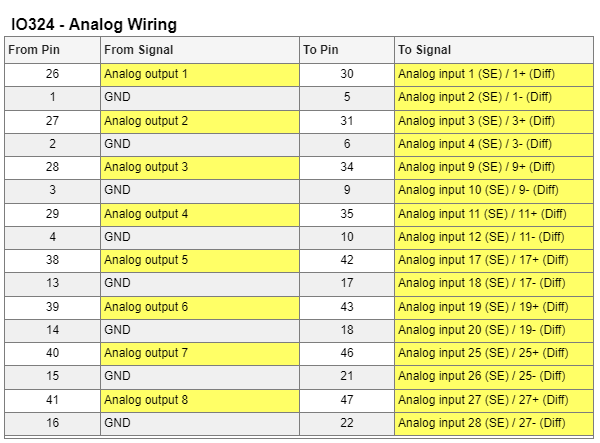

[IO324 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_200k_pin_mapping): please note that only the analog I/O of terminal board 2 are relevant for this example.

## Initialize and Open the Simulink Model

Open the Simulink model and choose your appropriate connection by commenting out the unwanted configuration block.

 
% Open Simulink model
modelName = 'sgMdl_IO324_AnalogLoopbackDMA';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select a configuration file. This example only requires analog interfaces, which are supported by any configuration file for the IO324 by default.

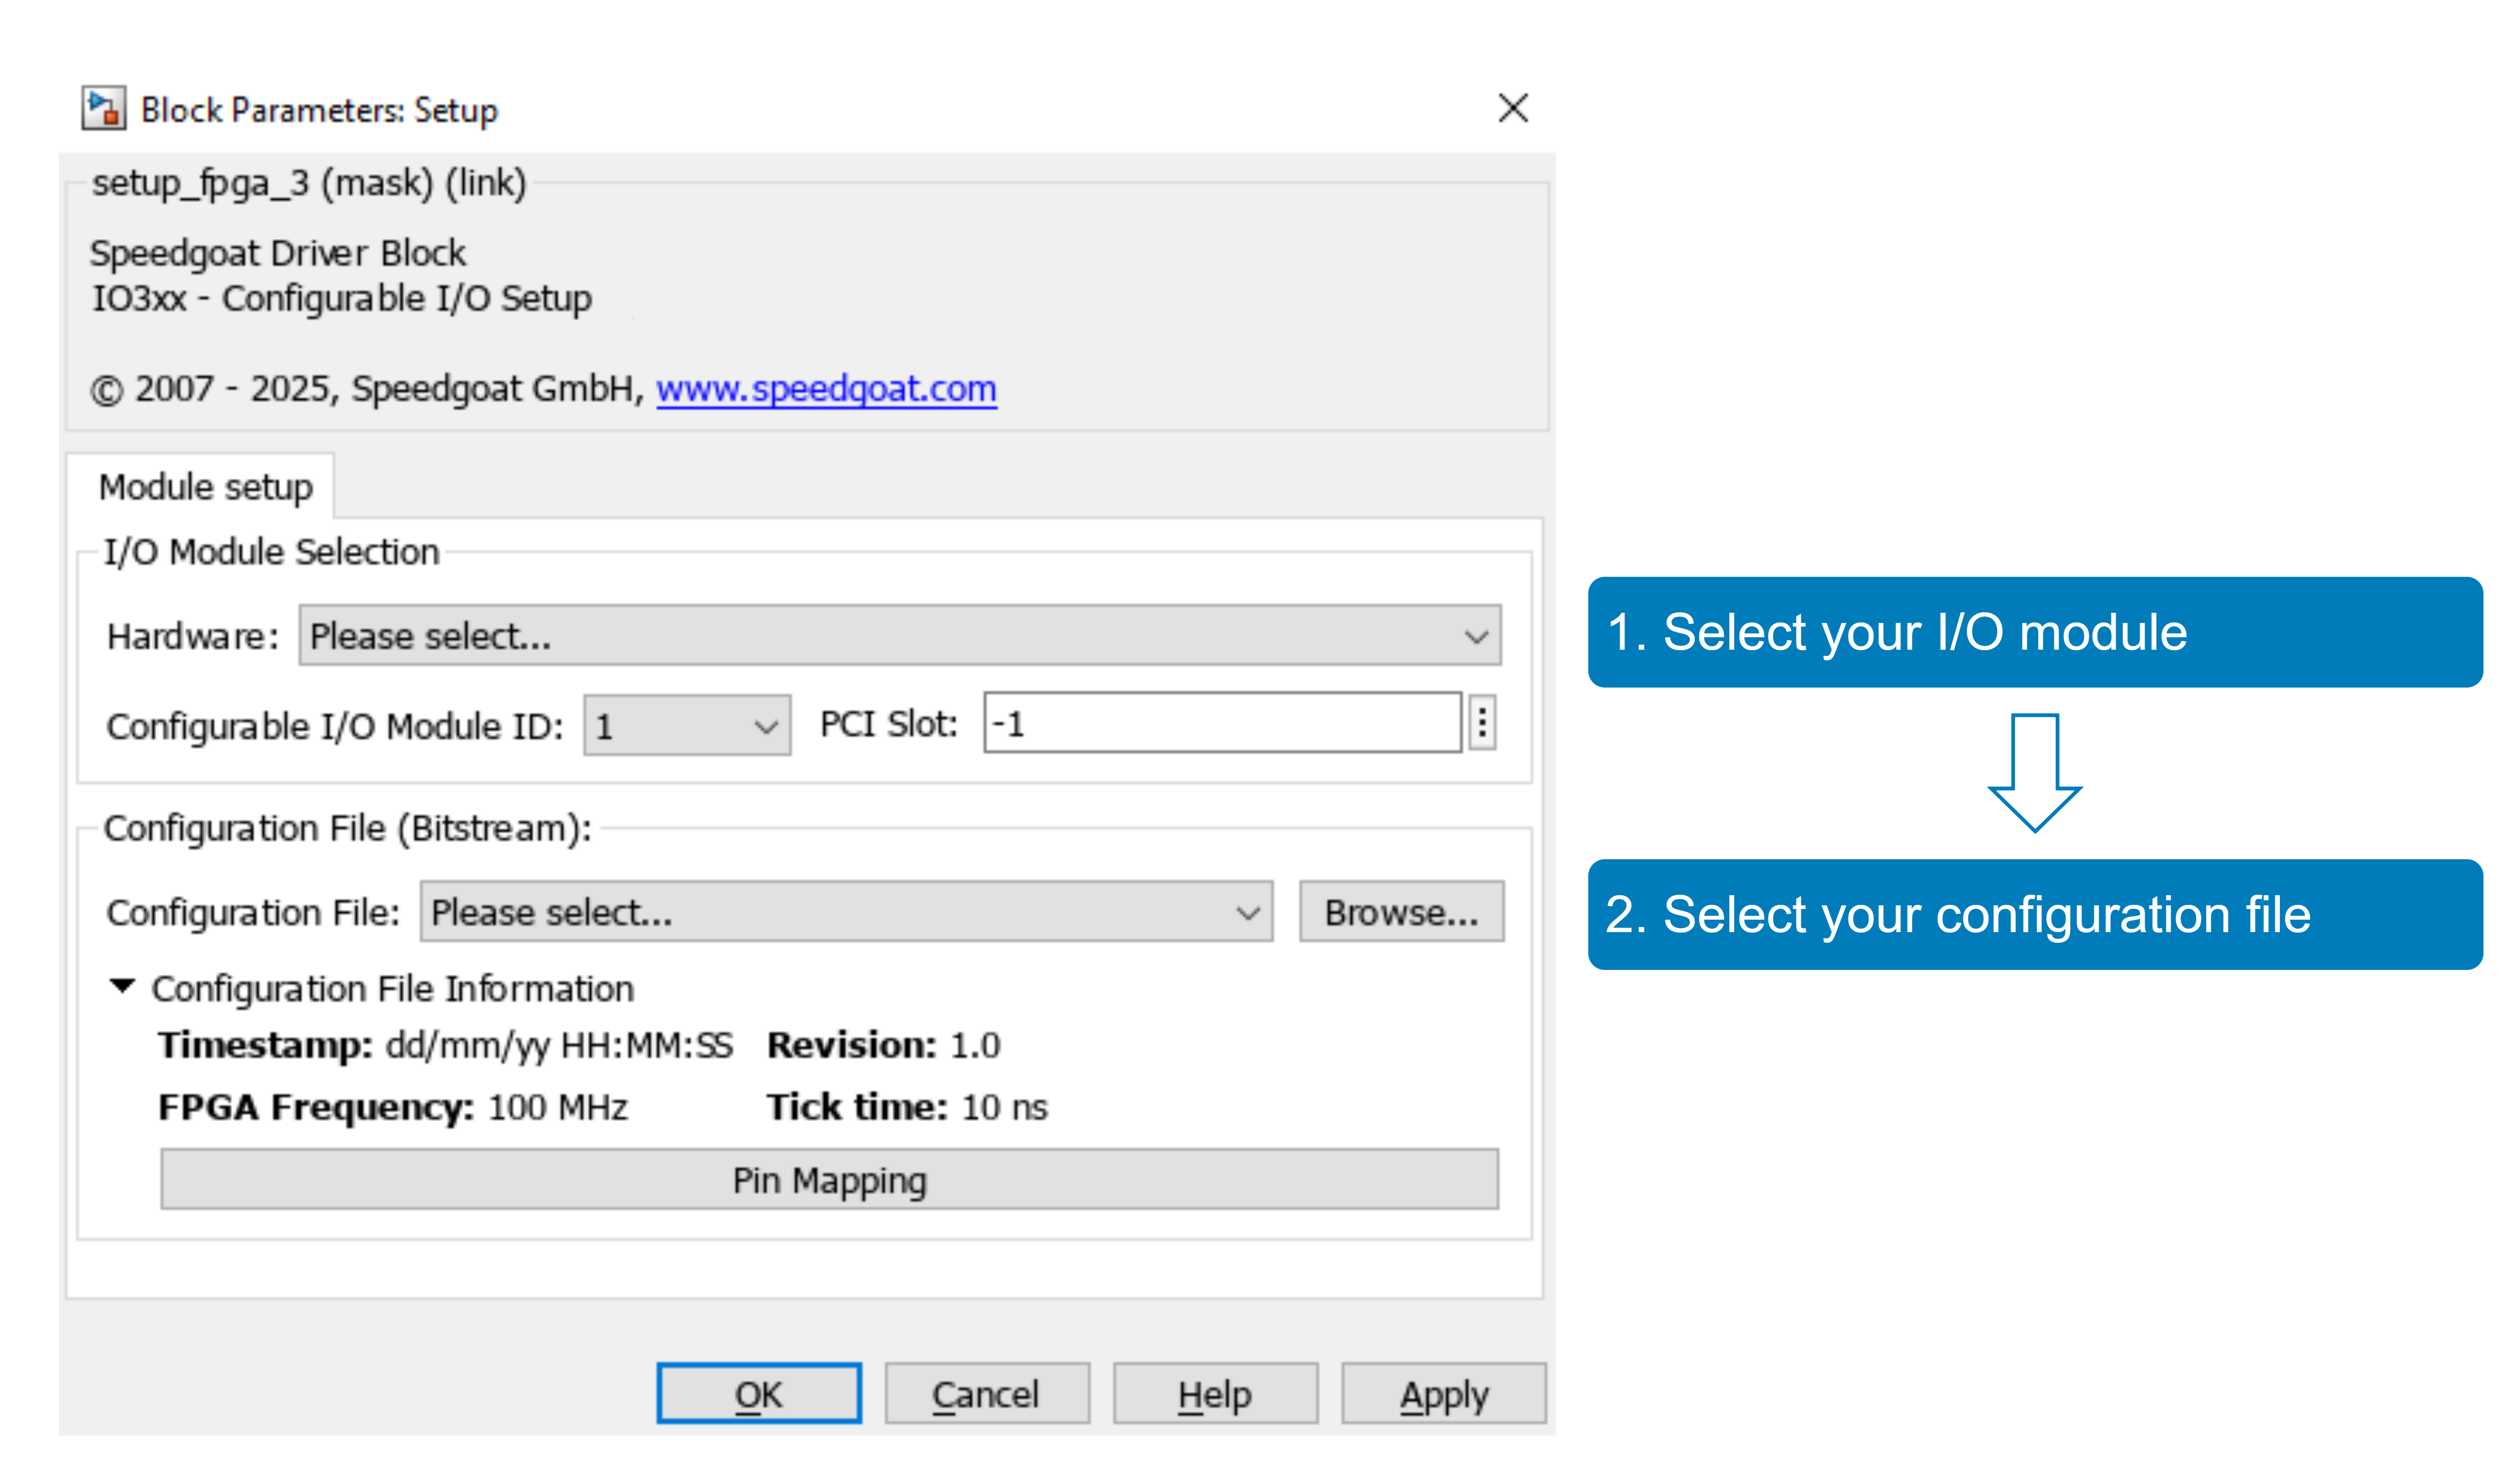

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### General Setup

The Simulink model features the [IO324 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_fpga_setup_io324_200k), [IO324 Analog Setup v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1), [IO324 Analog Input v1](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_input_v1), [IO324 Analog Output v1 ](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_output_v1)and the [Interrupt Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_interrupt_setup) blocks. The analog inputs and outputs of the IO324 are enabled in the [Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block. In this example the ADC and the DAC blocks are running in a frame-based mode.

The ADC is sampling a frame of a configurable number of signals with a configurable sampling rate. If a complete frame is sampled, an interrupt is generated that triggers the model (see **Interrupt Setup 1** block) where the ADC frames will be read.

The DAC outputs new values with a configurable sampling rate as well. The data for the DAC is a frame with a configurable size. A configurable number of DAC values before this frame is finished, an interrupt is generated (see **Interrupt Setup 2** block) that triggers a subsystem that is used to transfer the next complete frame to the DAC.

The model generates eight signals that are sent to the analog outputs of the IO324. Each signal is a sawtooth: whilst the first signal is in the range of -10 to 0, the second signal is in the range of -9 to 1, and so on. Given the loopback wiring, the same voltage values are read again on the analog inputs.

### ADC and DAC Settings

To see the setup and parametrization of the ADC and DAC channels, open the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block.

#### Tab: Main / Analog Input Trigger section

In the **Main** tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, the **Analog Input Trigger** section shows the ADC trigger settings of this model.

The **ADC Sample Trigger** parameter is set to **I/O Module Clock** and the **Enable DMA Interrupt** checkbox is enabled. The **ADC Sample Rate [Hz]** is set to 250 kHz, the **Frame Size (samples/channel)** is set to 100 and the **Input Block Sample Time [s]** is set to -1. This means the ADC will sample with a rate of 250 kHz and after 100 measurements, an interrupt will be triggered that can be used to read the complete frame.

The **Input Block Sample Time [s]** is set to -1. Consequently, the sample time is calculated based on the ADC sample rate and the frame size. Alternatively, you could also set the **Input Block Sample Time [s]** to 400e-6 and either set the **ADC Sample Rate [Hz]** or the **Frame Size (samples/channel)** to -1 which would result in the same behavior.

#### Tab: Main / Analog Output Trigger section

As for the input trigger, the **DAC Sample Trigger** is set to **I/O Module Clock** and the **Enable DMA Interrupt** checkbox is enabled. The **FIFO Threshold** is set to 25, the **DAC Sample Rate [Hz]** is set to 250 kHz, the **Frame Size (samples/channel)** is set to 1000 and the **Output Block Sample Time [s]** is set to -1. This means that you can define a frame of 1000 analog values that will be set to the DAC outputs with a rate of 250 kHz.

An interrupt will be triggered when the amount of last values (defined by the **FIFO Threshold**) are sent to the DAC. In this example, the **FIFO Threshold** is set to 25. This means that when 25 DAC values of the current frame are left, the interrupt is triggered and can be used to generate the next DAC frame. Since the **DAC Sample Rate [Hz]** is set to 250 kHz in this example, this means that the interrupt is triggered 25*1/250 kHz = 100 us before the frame ends so the part of the model that calculates the DAC values must have a TET below 100 us.

The relation of the **Output Block Sample Time [s], DAC Sample Rate [Hz]** and the **Frame Size (samples/channel)** is the same as for the input trigger. In this example for the outputs, a larger frame size is set (1000 samples/channel) and this will result in a larger sample time for the output block of 4 ms. 

#### Tab: Analog Inputs

In the **Analog Inputs** tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you can see which ADC channels are active and how they are configured. In this example, ADC channels 1 / 3 / 17 / 19 are configured as single ended and ADC channels 9 / 11 / 25 / 27 are configured as differential. This is why the test-setup of this example requires the differential ADC negative inputs to be connected to ground.

#### Tab: Analog Outputs

In the **Analog Outputs** tab of the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block, you can see which DAC channels are active and how they are configured. Note the special settings of **Initial Value [V]** and **Reset to Initial Value**. The **Initial Value [V]** is applied on the DAC outputs every time a new real-time application is loaded to the target. The channels that have **Reset to Initial Value** enabled will apply the **Initial Value [V]** when the real-time application is stopped. In this example, only the DAC channels 1 / 3 / 5 / 7 are configured to reset to the initial value at model stop.

### Timing Behavior of the Example Model

This example model uses the ADC Frame end to trigger: no timing trigger is used. In this situation, the system is not able to determine the time between two model steps. However, we use the ADC Frame Trigger as the model trigger source (see **Interrupt Setup 1** block) which occurs every 400 us as described above. For correct timing relations, we need to set the model step-time to the corresponding ADC Frame timing, which is 400 us in this example model:

 
% Mandatory: set the model time step to 400 us
% Whenever the model trigger source or the trigger timing is changed, this needs to be adapted here
set_param(modelName, 'FixedStep', '400e-6');

#### ADC

The following image describes the timing behavior of the ADC frame:

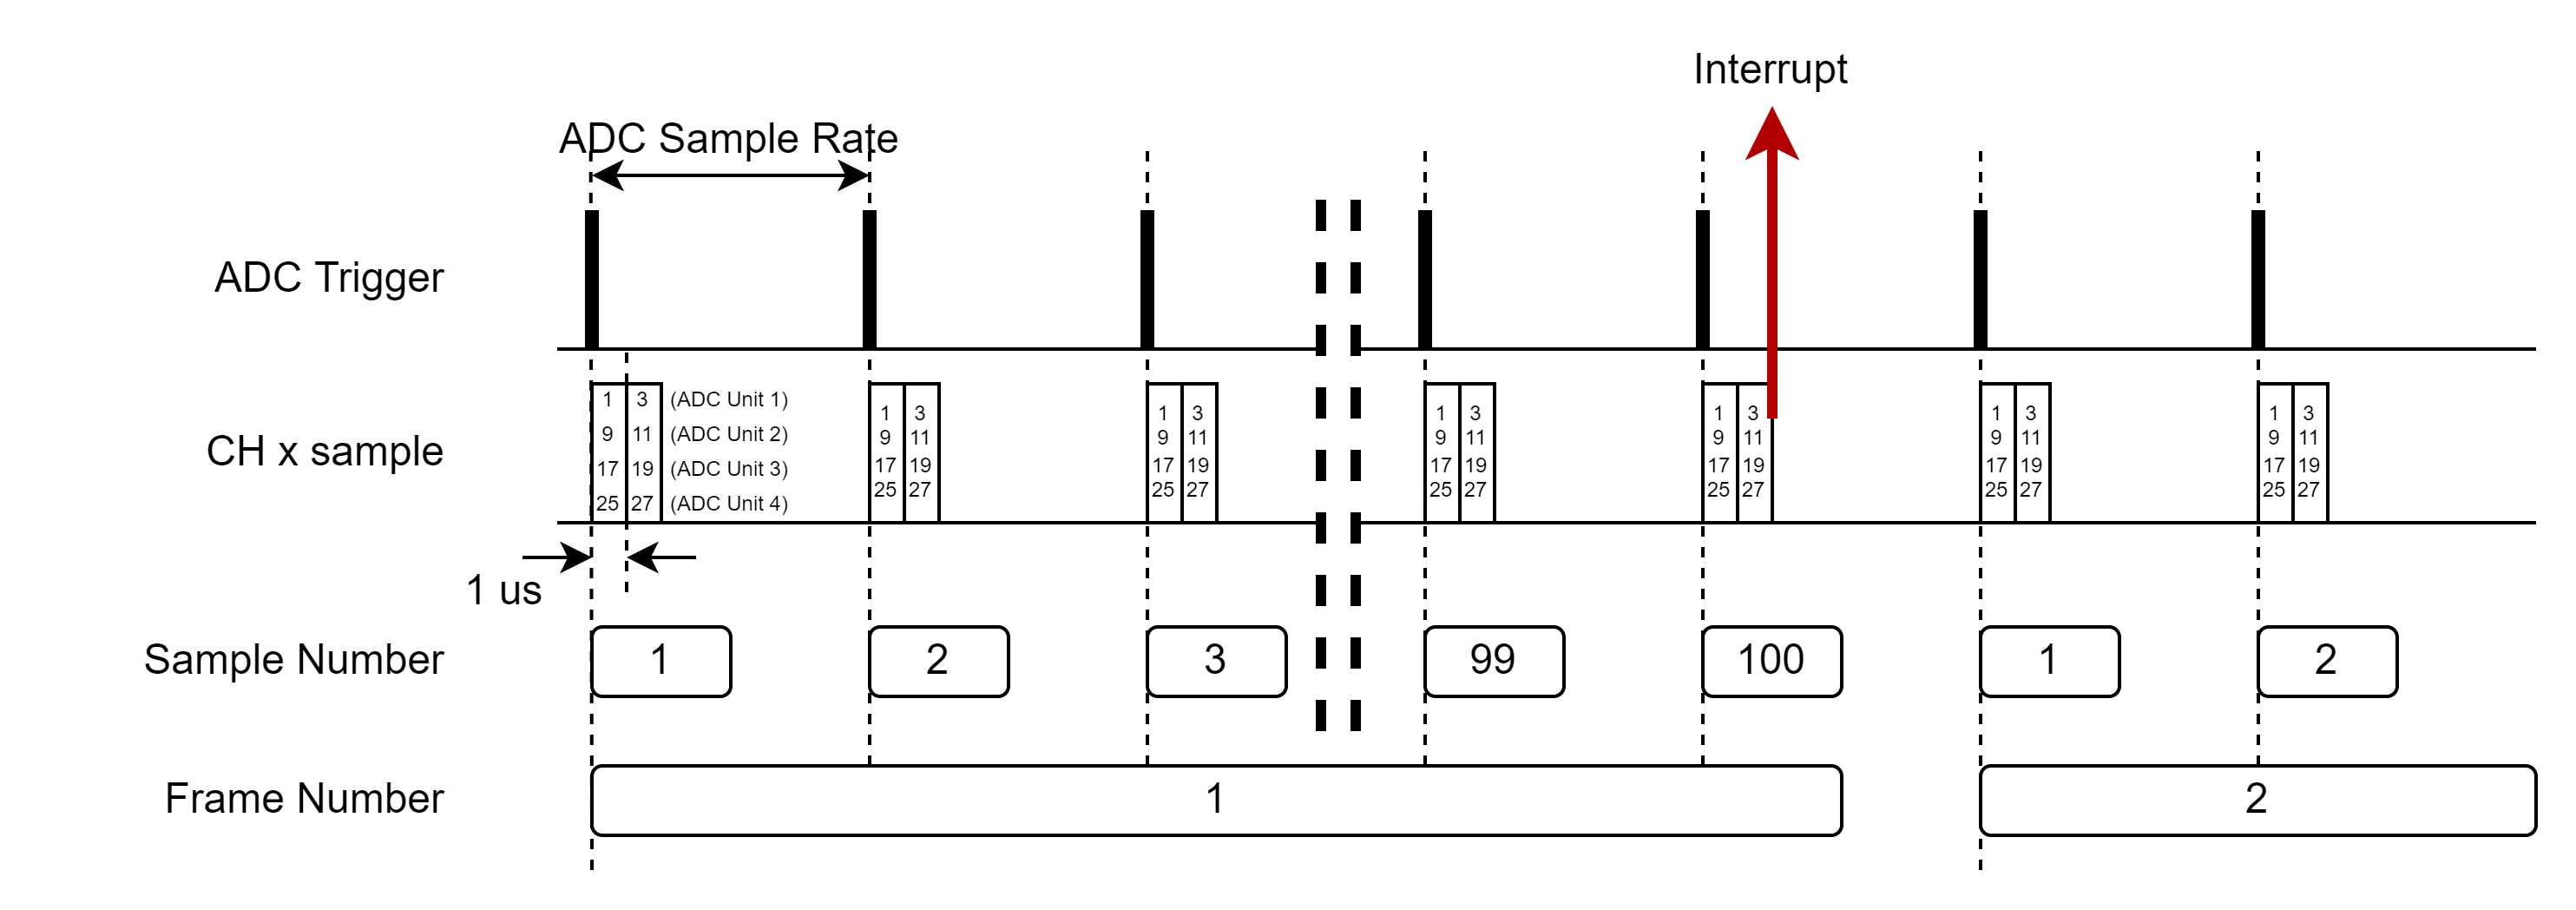

The ADCs are triggered with the **ADC Sample Rate [Hz]** (set to 250 kHz in this example). Note that the IO324 contains 4 ADC units whereas one unit contains 8 ADC channels that are converted in series. Each conversion takes 1 us to be processed. This example uses two ADC channels of each ADC unit (Channel 1 and 3 on ADC unit 1 / Channel 9 and 11 on ADC unit 2 / Channel 17 and 19 on ADC unit 3 / Channel 25 and 27 on ADC unit 4). Therefore, the ADC channels 1 / 9 / 17 / 25 are sampled by the ADC Trigger signal. The ADC channels 3 / 11 / 19 / 27 are sampled 1 us after the ADC Trigger signal.

When the number of samples reaches the specified **Frame Size (samples/channel)** (set to 100 in this example), the **Speedgoat IO324-200k Analog input interrupt** is generated. This interrupt can be used to either trigger the complete model or a [Function-Call Subsystem](https://mathworks.com/help/simulink/slref/functioncallsubsystem.html) in which the analog input vales can be read. 

#### DAC

The following image describes the timing behavior of the DAC Frame:

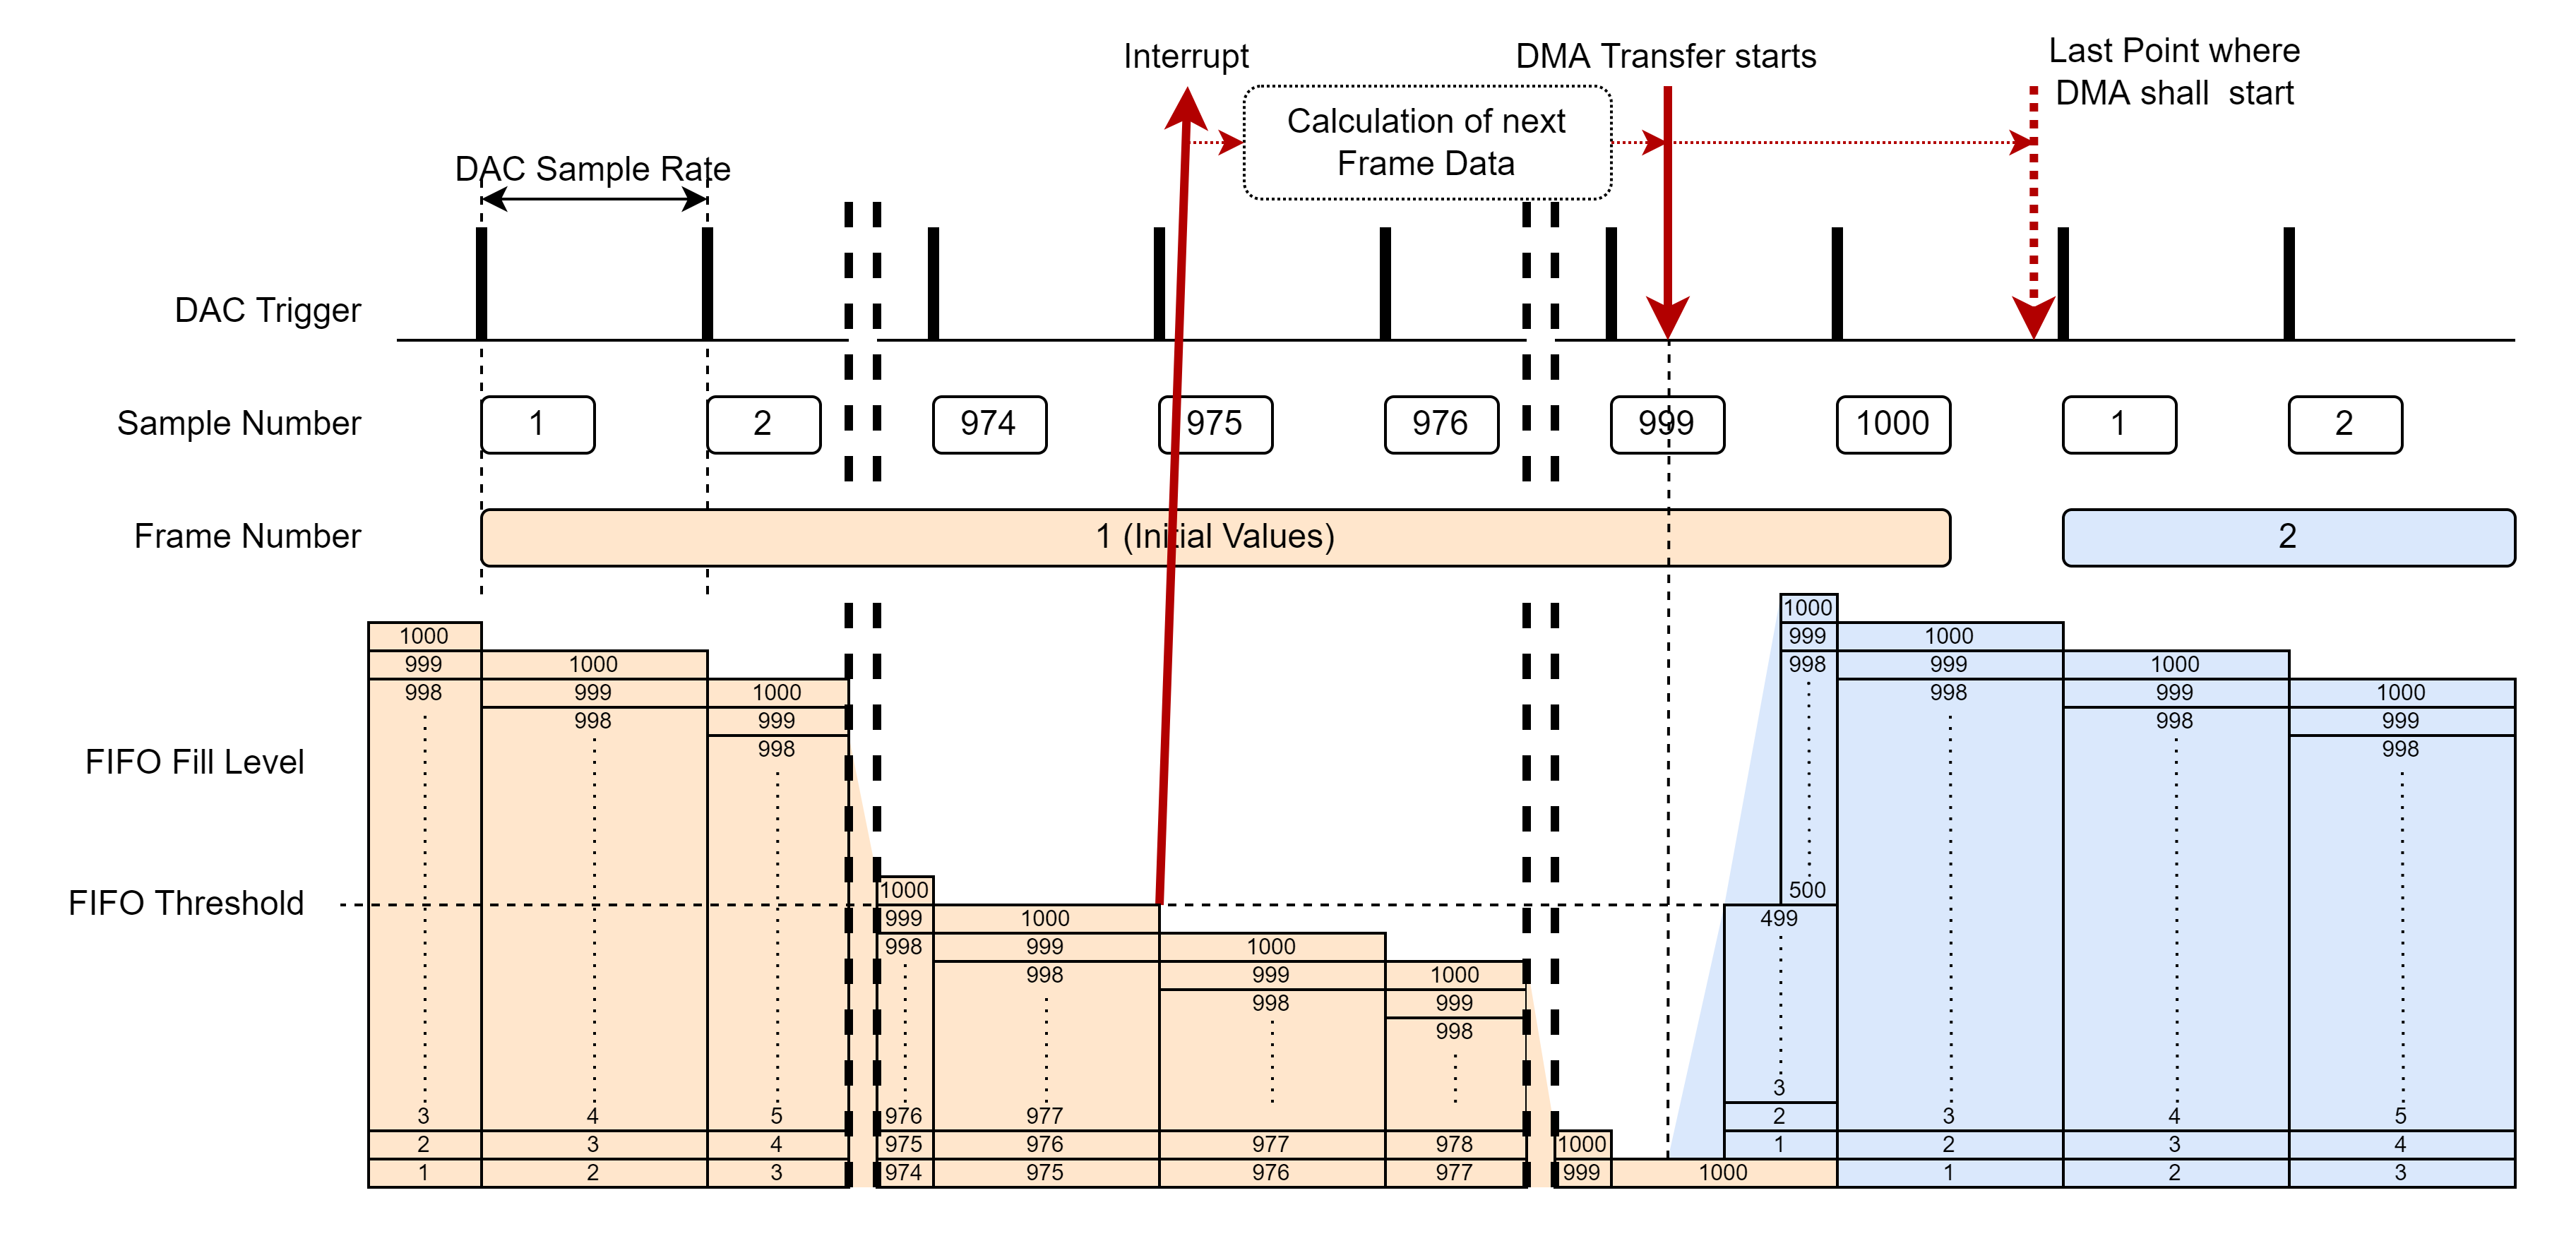

The DACs are triggered with the DAC** Sample Rate [Hz]** (set to 250 kHz in this example). Note that the IO324 contains 8 DAC channels that are updated synchronously. This example uses all 8 DAC channels.

The DAC samples are stored in an internal FIFO buffer. When the number of remaining samples in the FIFO falls below the **FIFO Threshold** (set to 25 in this example), the **Speedgoat IO324-200k Analog output interrupt** is generated that can be used to either trigger the complete model or a [Function-Call Subsystem](https://mathworks.com/help/simulink/slref/functioncallsubsystem.html) in which the next frame of DAC values is calculated. Please bear in mind the interrupt latency time, which comprises the execution of the CPU model to calculate the next frame and the setup of the DMA transfer. The **FIFO Threshold **needs to be set in such a way that the DAC FIFO fill level is not empty when the DAC trigger requests the 1st sample of the new frame. The upper limit of the **FIFO Threshold** is the same as the **Frame Size**.

Note that the very 1st DAC frame contains all the **DAC Initial Values [V]** defined in the [IO324 Analog Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io324_analog_setup_v1) block. This means that all used DAC outputs will be on their initial values for the time of the complete 1st frame.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Define and set stop-time
stoptime = 9.0016; % Simulation length [s]

tg.setStopTime(stoptime);

% Start the real-time application
tg.start;
pause(stoptime+1);

## Show and Analyze the Signals

To show the measured signals, either run the following code section or click the **Data Inspector** button in the **REAL-TIME** tab in the Simulink model.

 
% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(2,1);                     % layout with two plots

% get signals by name (signal label in Simulink)
CH1_Signal = SDIRun.getSignalsByName( 'CH1 (ADC 01 Single)');
CH2_Signal = SDIRun.getSignalsByName( 'CH3 (ADC 01 Single)');
CH3_Signal = SDIRun.getSignalsByName( 'CH9 (ADC 02 Diff)');
CH4_Signal = SDIRun.getSignalsByName('CH11 (ADC 02 Diff)');
CH5_Signal = SDIRun.getSignalsByName('CH17 (ADC 03 Single)');
CH6_Signal = SDIRun.getSignalsByName('CH19 (ADC 03 Single)');
CH7_Signal = SDIRun.getSignalsByName('CH25 (ADC 04 Diff)');
CH8_Signal = SDIRun.getSignalsByName('CH27 (ADC 04 Diff)');

% convert all signals to frames
convertToFrames(CH1_Signal);
convertToFrames(CH2_Signal);
convertToFrames(CH3_Signal);
convertToFrames(CH4_Signal);
convertToFrames(CH5_Signal);
convertToFrames(CH6_Signal);
convertToFrames(CH7_Signal);
convertToFrames(CH8_Signal);

% assign signals to subplots
plotOnSubPlot(CH1_Signal,1,1,true);
plotOnSubPlot(CH2_Signal,2,1,true);
plotOnSubPlot(CH3_Signal,2,1,true);
plotOnSubPlot(CH4_Signal,2,1,true);
plotOnSubPlot(CH5_Signal,2,1,true);
plotOnSubPlot(CH6_Signal,2,1,true);
plotOnSubPlot(CH7_Signal,2,1,true);
plotOnSubPlot(CH8_Signal,2,1,true);

% open SDI
Simulink.sdi.view;
Simulink.sdi.setSubplotLimits(1,1,"tMin",-0.0005,"tMax",0.01405);   % set time span
Simulink.sdi.setSubplotLimits(1,1,"yMin",-10.5,"yMax",0.5);         % set y-zoom of channel 1
Simulink.sdi.setSubplotLimits(2,1,"yMin",-9.5,"yMax",7.5);          % set y-zoom of other channels

### Check the Results

The SDI view shows you the generated DAC output values and the measured ADC input values. Note that the run took 9.5 s, but we only look into the first few milliseconds:

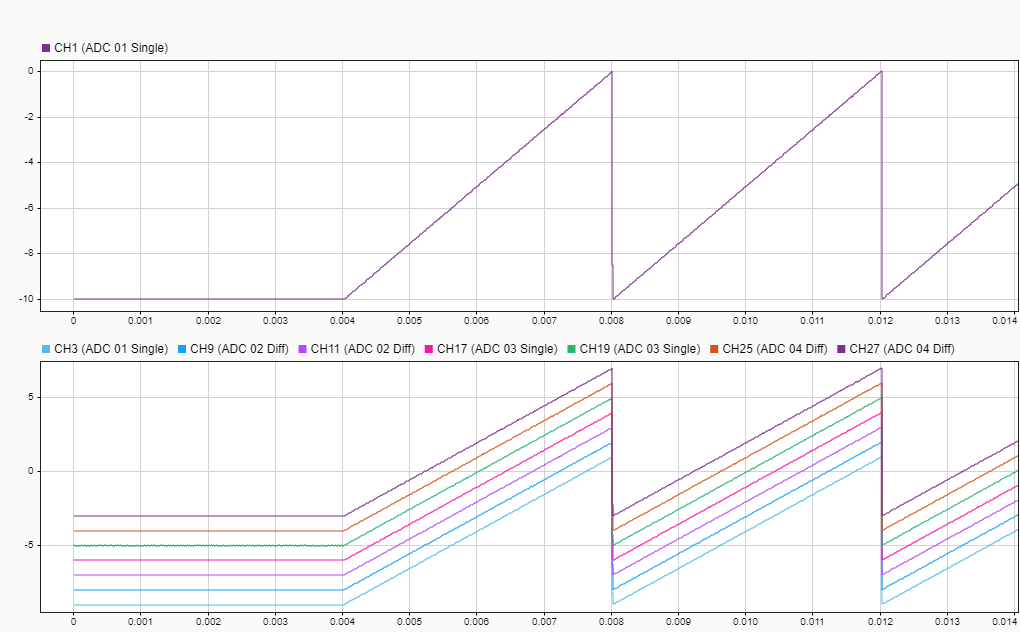

Each Signal is a sawtooth with a difference of 10 V. Channel 1 starts at -10 V, Channel 2 starts at -9 V, and so on. Note that the first DAC frame contains the initial values of the DAC as described above.

#### Measuring the DAC-Values after Model-Stop

Note that this plot shows the signals after the model was freshly built and run for the 1st time. The behavior will be a bit different for the following runs (if nothing changes on the model).

Remember that we set **Reset to Initial Value** on DAC channels 1 / 3 / 5 / 7, but not on DAC channels 2 / 4 / 6 / 8. Since the ADC is running in the frame-based mode and the ADC trigger is the same as the DAC, we will be able to see the last DAC values that were applied at the end of the execution of the real-time application at the very beginning of the next execution.

The following code re-runs the model and displays the results for the first millisecond:

 
% Just Re-load and Re-start the model again
tg.load(modelName);
stoptime = 9.0014; % Simulation length [s]
tg.setStopTime(stoptime);
tg.start;
pause(stoptime+1);

% Get and configure SDI Run
SDIRun      = Simulink.sdi.Run.getLatest;   % get the latest SDI run
SDIRun.name = 'Real-Time Simulation';

% clear and configure plot layout
Simulink.sdi.clearAllSubPlots
Simulink.sdi.setSubPlotLayout(1,1);                     % layout with two plots

% get signals by name (signal label in Simulink)
CH1_Signal = SDIRun.getSignalsByName( 'CH1 (ADC 01 Single)');
CH2_Signal = SDIRun.getSignalsByName( 'CH3 (ADC 01 Single)');
CH3_Signal = SDIRun.getSignalsByName( 'CH9 (ADC 02 Diff)');
CH4_Signal = SDIRun.getSignalsByName('CH11 (ADC 02 Diff)');
CH5_Signal = SDIRun.getSignalsByName('CH17 (ADC 03 Single)');
CH6_Signal = SDIRun.getSignalsByName('CH19 (ADC 03 Single)');
CH7_Signal = SDIRun.getSignalsByName('CH25 (ADC 04 Diff)');
CH8_Signal = SDIRun.getSignalsByName('CH27 (ADC 04 Diff)');

% convert all signals to frames
convertToFrames(CH1_Signal);
convertToFrames(CH2_Signal);
convertToFrames(CH3_Signal);
convertToFrames(CH4_Signal);
convertToFrames(CH5_Signal);
convertToFrames(CH6_Signal);
convertToFrames(CH7_Signal);
convertToFrames(CH8_Signal);

% assign signals to subplots
plotOnSubPlot(CH1_Signal,1,1,true);
plotOnSubPlot(CH2_Signal,1,1,true);
plotOnSubPlot(CH3_Signal,1,1,true);
plotOnSubPlot(CH4_Signal,1,1,true);
plotOnSubPlot(CH5_Signal,1,1,true);
plotOnSubPlot(CH6_Signal,1,1,true);
plotOnSubPlot(CH7_Signal,1,1,true);
plotOnSubPlot(CH8_Signal,1,1,true);

% open SDI
Simulink.sdi.setSubplotLimits(1,1,"yMin",-10.5,"yMax",7.5);     % set y-zoom of channel 1
Simulink.sdi.setSubplotLimits(1,1,"tMin",-0.0001,"tMax",0.001); % set time span
CH2_Signal.LineWidth = 4;
CH4_Signal.LineWidth = 4;
CH6_Signal.LineWidth = 4;
CH8_Signal.LineWidth = 4;
Simulink.sdi.view;
pause(1);
% set cursor on Position 0
Simulink.sdi.setNumCursors(1);
Simulink.sdi.setCursorPositions('left',0);

Now if we look at the signals in the first millisecond:

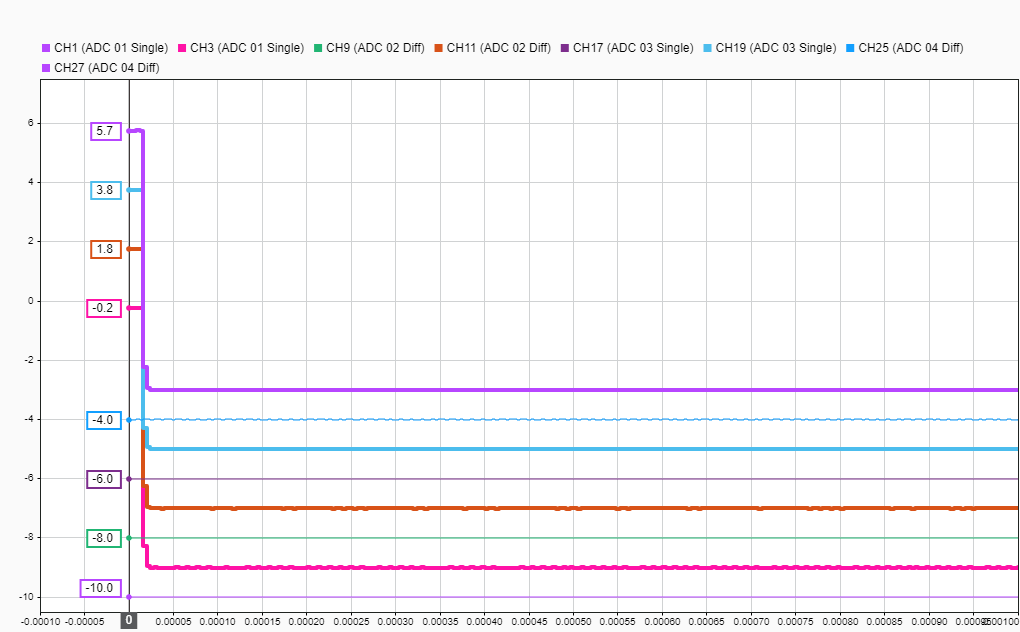

ADC1 CH2, ADC2 CH2, ADC3 CH2 and ADC4 CH2 have are different compared to the initial value. This is because we did not reset them to the initial value at the end of the last execution. The very first samples of these ADC channels are therefore the last DAC values of the previous execution.

Note: As the frame triggering is quite high (250 kHz), the ADC data which are not set to their initial values may be different on another run. This is because the timing of the model stop is not as accurate as the frame trigger generated on the IO324 FPGA.

## Additional References

- [IO324 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io324_200k)

- [Analog IO324](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_analog_io324_200k)